# **Simple vector field divergence analysis**

Divergence of a vector field F is the dot product of the delta operator with F.


$$div F = \nabla \cdot F = \frac{\partial{F_x}}{\partial{x}} + \frac{\partial{F_y}}{\partial{y}}$$


**Goal: Understand how divergence is calculated and implemented in MATLAB.**

In this MATLAB notebook, we also look at the Laplacian and curl of the vector field. However, this is a side note of this notebook.

## **Section 1: Testing source point using minimally required flow line**

Let's look at flow lines that are straight lines directed away from the origin.

[X,Y] = meshgrid(-1:1:1);
dX = X; dY = Y;
Divergence1 = divergence(X,Y,dX,dY)

Divergence1 =      2     2     2
     2     2     2
     2     2     2


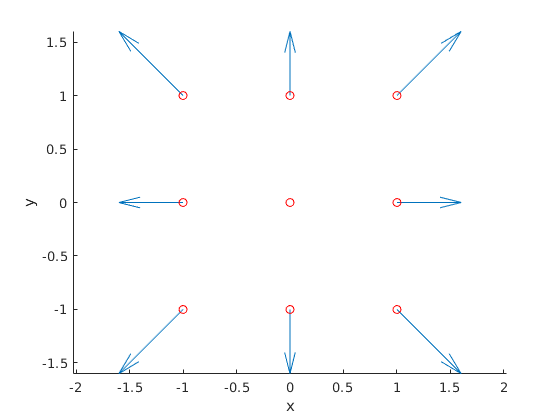

figure, hold on
xlabel('x'); ylabel('y'); axis equal
quiver(X, Y, dX, dY);
scatter(X(:),Y(:),'r','o');

We see here that divergence is 2 everywhere, meaning that the space is homogeneously expanding to twice its size everywhere.

**What if we have vectors pointing towards and away from the origin at the same time?**

[X,Y] = meshgrid(-1:1:1); 
dX = X; dY = Y;
dX([1 3 5 7 9]) = -1*dX([1 3 5 7 9]);
dY([1 3 5 7 9]) = -1*dY([1 3 5 7 9]);
Divergence1 = divergence(X,Y,dX,dY)

Divergence1 =     -2     0    -2
     0     2     0
    -2     0    -2


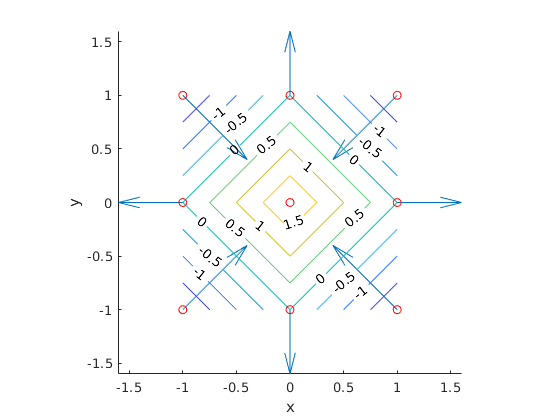

figure, hold on
xlabel('x'); ylabel('y'); axis equal
quiver(X, Y, dX, dY); contour(X,Y,Divergence1,'ShowText',"on")
scatter(X(:),Y(:),'r','o');

**What if we reduce the number of datapoint?** The function will not have enough datapoints to compute divergence

[X,Y] = meshgrid(-1:1:1);
X([1 3 5 7 9]) = NaN;
Y([1 3 5 7 9]) = NaN;
dX = X;
dY = Y;
Divergence1 = divergence(X,Y,dX,dY)

Divergence1 =    NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


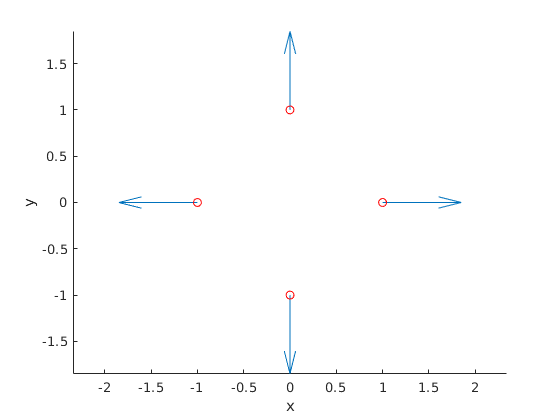

figure, hold on
xlabel('x'); ylabel('y'); axis equal
quiver(X, Y, dX, dY);
scatter(X(:),Y(:),'r','o');

We see here that divergence cannot be computed, because for each available datapoint, its neighbor is missing.

**What if we use the Laplacian instead? **

**The Laplacian measures the curvature and variation of the vector field, while the divergence measures the flow of the vector field.**

[X,Y] = meshgrid(-1:1:1);
dX = X; dY = Y;
lap_dX = del2(dX)

lap_dX =      0     0     0
     0     0     0
     0     0     0


lap_dY = del2(dY)

lap_dY =      0     0     0
     0     0     0
     0     0     0


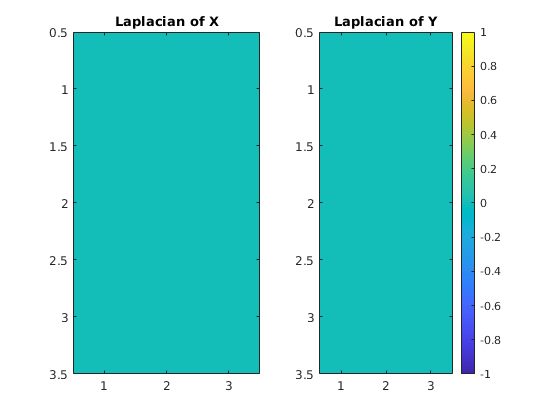

subplot(1,2,1);imagesc(lap_dX); title('Laplacian of X')
subplot(1,2,2);imagesc(lap_dY); title('Laplacian of Y'); colorbar

We see here that the Laplacian is 0 everywhere, because there is no curvature or variation in the vector field.

## **Section 2: Testing a vector field with a source fixed point (left) and a sink fixed point (right)**

Let's create a function Z2 to create our vector field with source and sink.

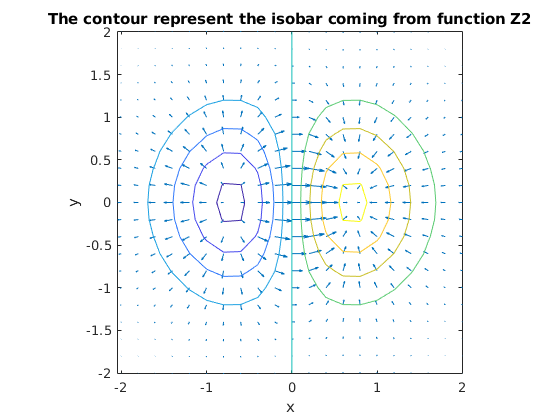

spacing = 0.2;
[X2,Y2] = meshgrid(-2:spacing:2);
Z2 = X2.*exp(-X2.^2 - Y2.^2);
[DX2,DY2] = gradient(Z2,spacing);

% Display the gradient vectors.
figure, quiver(X2,Y2,DX2,DY2); hold on
contour(X2,Y2,Z2); axis equal
xlabel('x'); ylabel('y'); title('The contour represent the isobar coming from function Z2')
hold off

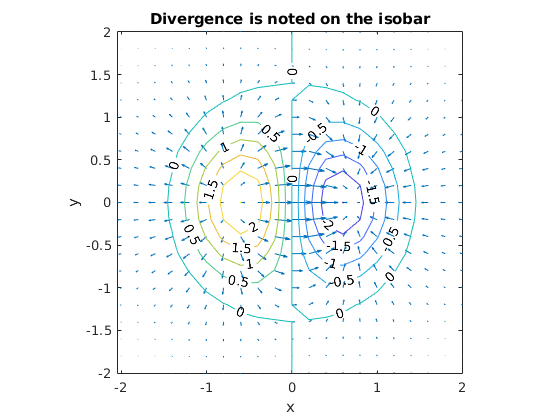

% Calculate & visualize divergence
Dtest2 = divergence(X2,Y2,DX2,DY2);

figure, quiver(X2,Y2,DX2,DY2); hold on
axis equal
xlabel('x'); ylabel('y'); title('Divergence is noted on the isobar')
contour(X2,Y2,Dtest2,'ShowText','on')
hold off

Checking its Laplacian:

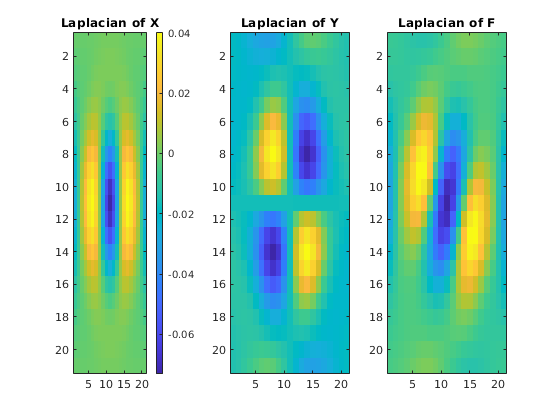

lap_dX2 = del2(DX2);
lap_dY2 = del2(DY2);
lap_d2 = lap_dX2 + lap_dY2;
subplot(1,3,1);imagesc(lap_dX2); title('Laplacian of X'); colorbar
subplot(1,3,2);imagesc(lap_dY2); title('Laplacian of Y')
subplot(1,3,3);imagesc(lap_d2); title('Laplacian of F'); 

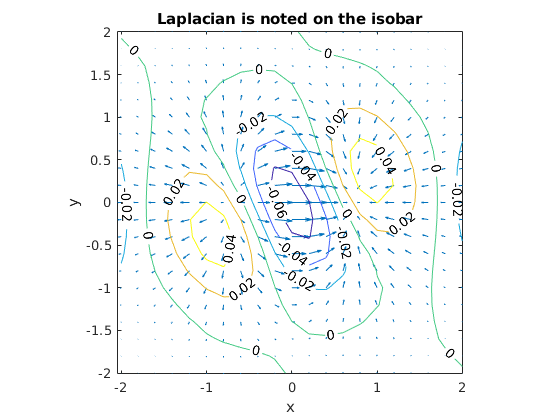

figure, quiver(X2,Y2,DX2,DY2); hold on
axis equal
xlabel('x'); ylabel('y'); title('Laplacian is noted on the isobar')
contour(X2,Y2,lap_d2,'ShowText','on')
hold off

The Laplacian is hard to visualize, but one can imagine it here as measuring the concavity of the surface, or the magnitude of the divergence compared to its neighbor. Imagine here we are looking down at a mountain with two valleys, the mountain peak has strongly negative Laplacian, indicating the surrounding divergence is smaller than the peak's divergence. The valleys are vice versa.

## **Section 3: Testing a rotating vector field without any source or sink fixed point**

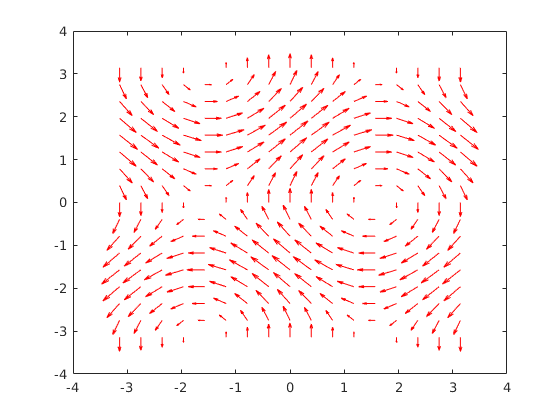

% Divergence of rotating vector field
[X3,Y3] = meshgrid(-pi:pi/8:pi,-pi:pi/8:pi); 
U3 = sin(Y3); % change in X
V3 = cos(X3); % change in Y
figure, quiver(X3,Y3,U3,V3,'r') % r makes the field red

D3 = divergence(X3,Y3,U3,V3)

D3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0  

Divergence is 0, showing that the field is neither a source nor a sink of fluid on average over the region.

**Checking its Laplacian:**

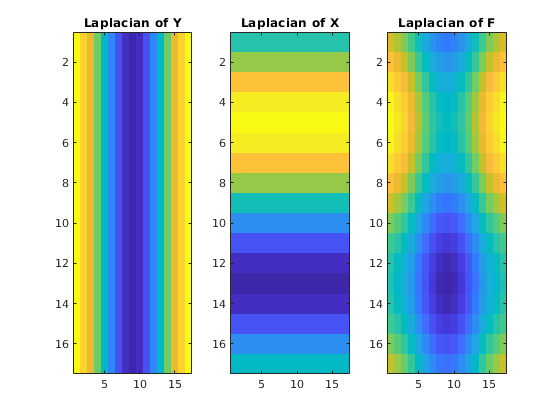

lap_V3 = del2(V3); % change in Y
lap_U3 = del2(U3); % change in X
lap_d3 = lap_U3 + lap_V3;
subplot(1,3,1);imagesc(lap_V3); title('Laplacian of Y')
subplot(1,3,2);imagesc(lap_U3); title('Laplacian of X')
subplot(1,3,3);imagesc(lap_d3); title('Laplacian of F')

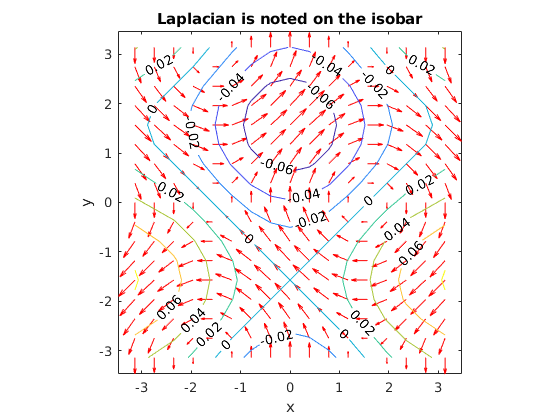

figure, quiver(X3,Y3,U3,V3,'r'); hold on
axis equal
xlabel('x'); ylabel('y'); title('Laplacian is noted on the isobar')
contour(X3,Y3,lap_d3,'ShowText','on')
hold off

The Laplacian tells us the the curvature and variation of the vector field. We can see here that at the center of rotation, there is no change in curvature or variation, hence the Laplacian is 0.

For rotating vector field, it may be more informative to find the numerical curl and angular velocity. 

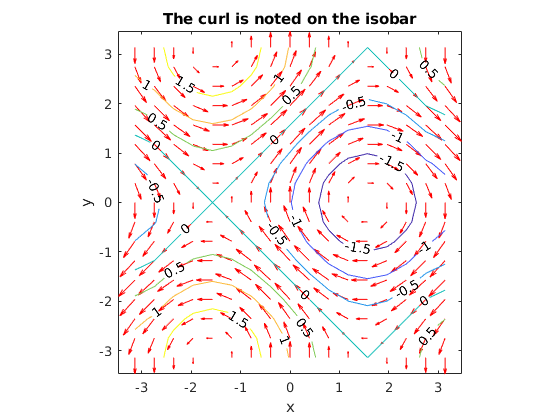

[curlz,cav] = curl(X3,Y3,U3,V3);
figure, quiver(X3,Y3,U3,V3,'r'); hold on
axis equal
xlabel('x'); ylabel('y'); title('The curl is noted on the isobar')
contour(X3,Y3,curlz,'ShowText','on')
hold off

## **Section 4: Testing vector fields with again, sink and source, and rotation**

[X4,Y4] = meshgrid(0:pi/8:pi,-pi:pi/8:pi);
U4_1 = sin(X4); V4_1 = cos(Y4);
U4_2 = sin(Y4); V4_2 = cos(X4); 
Dleft = divergence(X4,Y4,U4_1,V4_1)

Dleft =     1.1683    1.0942    0.8829    0.5668    0.1938   -0.1791   -0.4952   -0.7065   -0.7807
    1.3474    1.2732    1.0620    0.7458    0.3729    0.0000   -0.3161   -0.5274   -0.6016
    1.6636    1.5894    1.3781    1.0620    0.6891    0.3161    0.0000   -0.2112   -0.2854
    1.8748    1.8006    1.5894    1.2732    0.9003    0.5274    0.2112    0.0000   -0.0742
    1.9490    1.8748    1.6636    1.3474    0.9745    0.6016    0.2854    0.0742         0
    1.8748    1.8006    1.5894    1.2732    0.9003    0.5274    0.2112         0   -0.0742
    1.6636    1.5894    1.3781    1.0620    0.6891    0.3161         0   -0.2112   -0.2854
    1.3474    1.2732    1.0620    0.7458    0.3729         0   -0.3161   -0.5274   -0.6016
    0.9745    0.9003    0.6891    0.3729         0   -0.3729   -0.6891   -0.9003   -0.9745
    0.6016    0.5274    0.3161    0.0000   -0.3729   -0.7458   -1.0620   -1.2732   -1.3474


Dright= divergence(X4,Y4,U4_2,V4_2)

Dright =      0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0


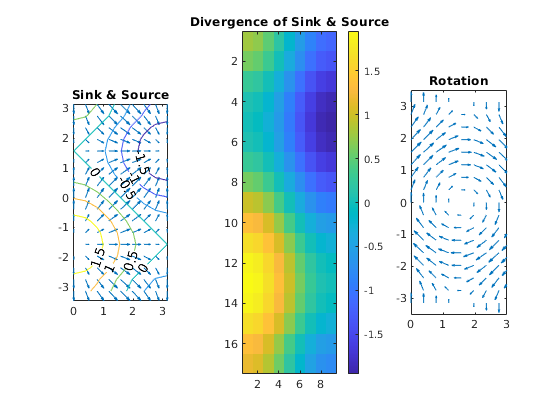

tiledlayout(1,3)

ax1 = nexttile;
quiver(ax1,X4,Y4,U4_1,V4_1)
axis equal
title(ax1,'Sink & Source')
hold on
contour(X4,Y4,Dleft,'ShowText','on')
hold off

nexttile; imagesc(flipud(Dleft)); colorbar % flipping matrix for display purpose
title('Divergence of Sink & Source')

ax3 = nexttile;
quiver(ax3,X4,Y4,U4_2,V4_2)
axis equal
ylim([-3.5 3.5]); xlim([0 3])
title(ax3,'Rotation')

## **Section 5: Test how divergence function handle missing data (represented by NaN)**

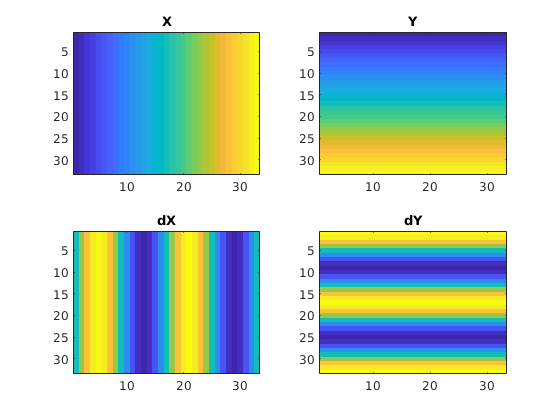

[X5,Y5] = meshgrid(-2*pi:pi/8:2*pi,-2*pi:pi/8:2*pi);
U5 = sin(X5);
V5 = cos(Y5);

figure
subplot(2,2,1); imagesc(X5); title('X')
subplot(2,2,2); imagesc(Y5); title('Y')
subplot(2,2,3); imagesc(U5); title('dX')
subplot(2,2,4); imagesc(V5); title('dY')

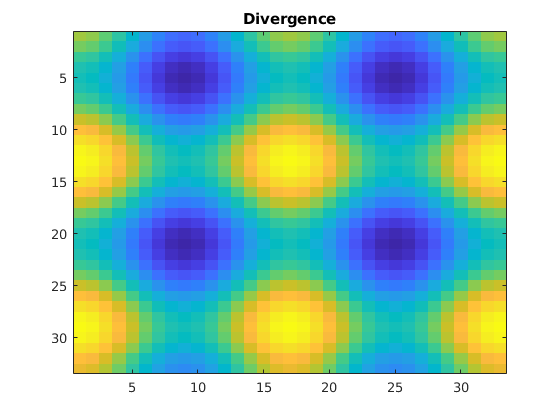

D5 = divergence(X5,Y5,U5,V5); 
figure, imagesc(D5); title('Divergence')

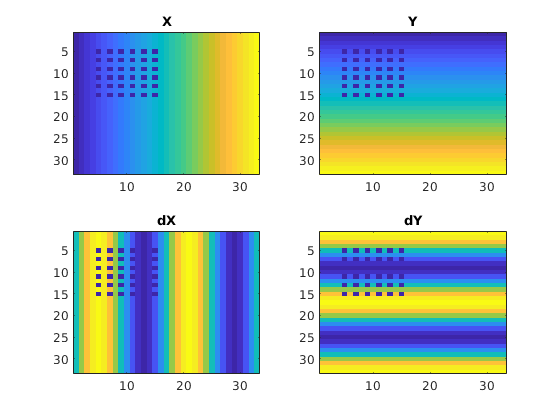


X5_2 = X5; X5_2(5:2:15,5:2:15) = NaN; 
Y5_2 = Y5; Y5_2(5:2:15,5:2:15) = NaN; 
U5_2 = sin(X5_2); 
V5_2 = cos(Y5_2);
figure
subplot(2,2,1); imagesc(X5_2); title('X')
subplot(2,2,2); imagesc(Y5_2); title('Y')
subplot(2,2,3); imagesc(U5_2); title('dX')
subplot(2,2,4); imagesc(V5_2); title('dY')

D5_2 = divergence(X5_2,Y5_2,U5_2,V5_2)

D5_2 =     0.7807    0.7065    0.4952    0.1791   -0.1938   -0.5668   -0.8829   -1.0942   -1.1683   -1.0942   -0.8829   -0.5668   -0.1938    0.1791    0.4952    0.7065    0.7807    0.7065    0.4952    0.1791   -0.1938   -0.5668   -0.8829   -1.0942   -1.1683   -1.0942   -0.8829   -0.5668   -0.1938    0.1791    0.4952    0.7065    0.7807
    0.6016    0.5274    0.3161   -0.0000   -0.3729   -0.7458   -1.0620   -1.2732   -1.3474   -1.2732   -1.0620   -0.7458   -0.3729   -0.0000    0.3161    0.5274    0.6016    0.5274    0.3161   -0.0000   -0.3729   -0.7458   -1.0620   -1.2732   -1.3474   -1.2732   -1.0620   -0.7458   -0.3729   -0.0000    0.3161    0.5274    0.6016
    0.2854    0.2112   -0.0000   -0.3161   -0.6891   -1.0620   -1.3781   -1.5894   -1.6636   -1.5894   -1.3781   -1.0620   -0.6891   -0.3161   -0.0000    0.2112    0.2854    0.2112   -0.0000   -0.3161   -0.6891   -1.0620   -1.3781   -1.5894   -1.6636   -1.5894   -1.3781   -1.0620   -0.6891   -0.3161   -0.0000    0.2112    0.2854


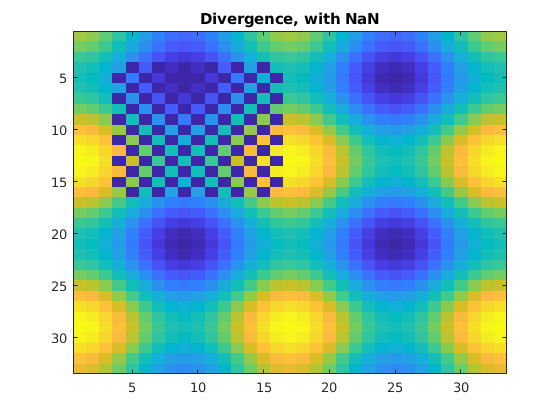

figure, imagesc(D5_2); title('Divergence, with NaN')

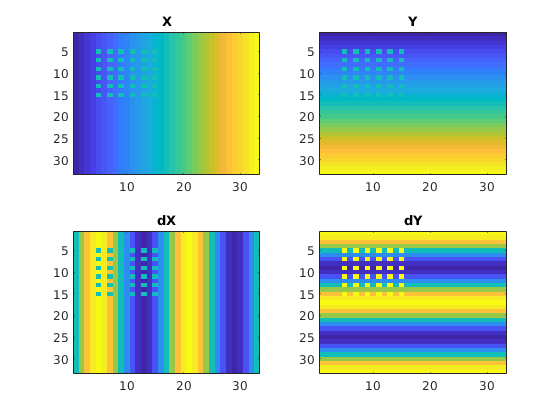

X5_3 = X5; X5_3(5:2:15,5:2:15) = eps; 
Y5_3 = Y5; Y5_3(5:2:15,5:2:15) = eps; 
U5_3 = sin(X5_3); 
V5_3 = cos(Y5_3);
figure
subplot(2,2,1); imagesc(X5_3); title('X')
subplot(2,2,2); imagesc(Y5_3); title('Y')
subplot(2,2,3); imagesc(U5_3); title('dX')
subplot(2,2,4); imagesc(V5_3); title('dY')

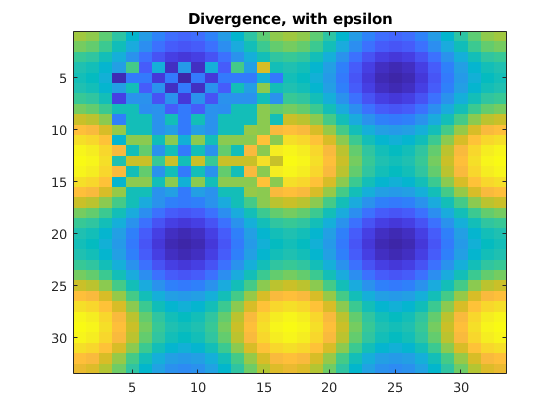

D5_3 = divergence(X5_3,Y5_3,U5_3,V5_3);
figure, imagesc(D5_3); title('Divergence, with epsilon')
figure, tiledlayout(1,3)

X5_4 = X5; X5_4(5:2:15,5:2:15) = 0; 
Y5_4 = Y5; Y5_4(5:2:15,5:2:15) = 0; 
U5_4 = sin(X5_4); 
V5_4 = cos(Y5_3);
figure
subplot(2,2,1); imagesc(X5_4); title('X')
subplot(2,2,2); imagesc(Y5_4); title('Y')
subplot(2,2,3); imagesc(U5_4); title('dX')
subplot(2,2,4); imagesc(V5_4); title('dY')

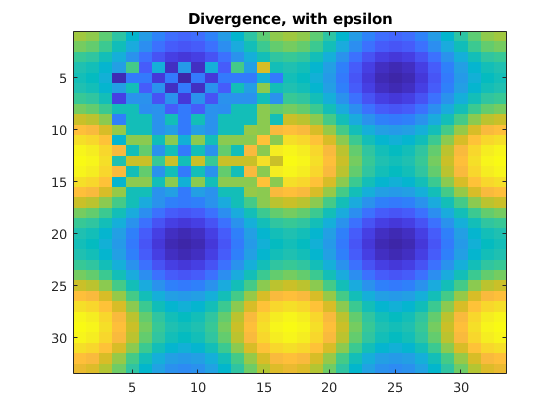

D5_4 = divergence(X5_4,Y5_4,U5_4,V5_4);
figure, imagesc(D5_4); title('Divergence, with epsilon')

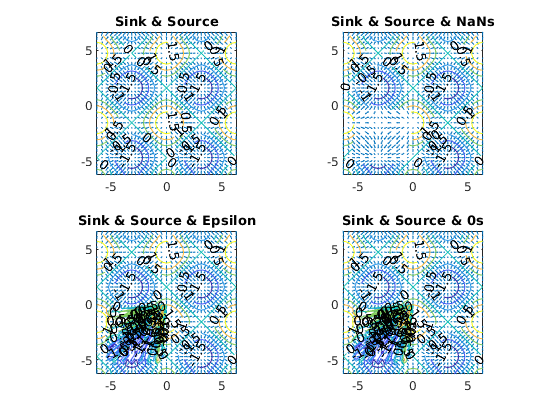

subplot(2,2,1)
quiver(X5,Y5,U5,V5)
axis equal
title('Sink & Source')
hold on
contour(X5,Y5,D5,'ShowText','on')
hold off

subplot(2,2,2)
quiver(X5_2,Y5_2,U5_2,V5_2)
axis equal
title('Sink & Source & NaNs')
hold on
contour(X5_2,Y5_2,D5_2,'ShowText','on')
hold off

subplot(2,2,3)
quiver(X5_3,Y5_3,U5_3,V5_3)
axis equal
title('Sink & Source & Epsilon')
hold on
contour(X5_3,Y5_3,D5_3,'ShowText','on')
hold off

subplot(2,2,4)
quiver(X5_4,Y5_4,U5_4,V5_4)
axis equal
title('Sink & Source & 0s')
hold on
contour(X5_4,Y5_4,D5_4,'ShowText','on')
hold off

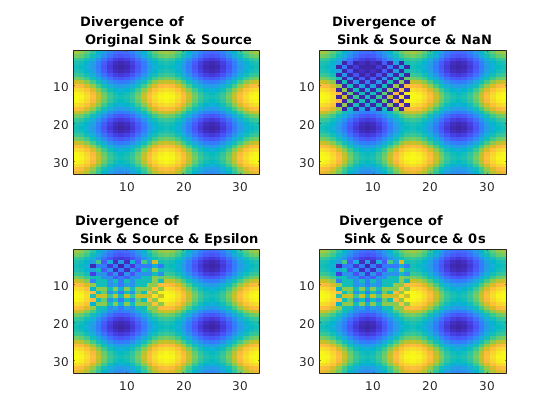

figure

subplot(2,2,1); imagesc(D5); title('Divergence of \newline Original Sink & Source')
subplot(2,2,2); imagesc(D5_2); title('Divergence of \newline Sink & Source & NaN')
subplot(2,2,3); imagesc(D5_3); title('Divergence of \newline Sink & Source & Epsilon')
subplot(2,2,4); imagesc(D5_4); title('Divergence of \newline Sink & Source & 0s')

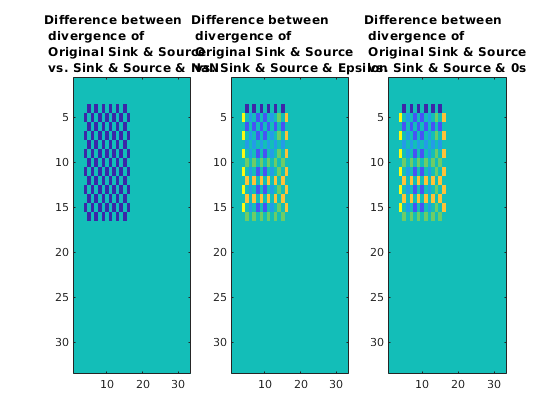

figure, tiledlayout(1,3)
diffNan = D5 - D5_2; 
diffEps = D5 - D5_3; 
diff0 = D5 - D5_4; 
nexttile; imagesc(diffNan); title('Difference between \newline divergence of \newline Original Sink & Source \newline vs. Sink & Source & NaN')
nexttile; imagesc(diffEps); title('Difference between \newline divergence of \newline Original Sink & Source \newline vs. Sink & Source & Epsilon')
nexttile; imagesc(diff0); title('Difference between \newline divergence of \newline Original Sink & Source \newline vs. Sink & Source & 0s')